绘制分泳道的热图

热图是一种简单直观呈现NTATS的方法。每组表现为一个泳道，泳道内是一张热图，用渐变颜色表示数值大小。

## 语法

## 示例

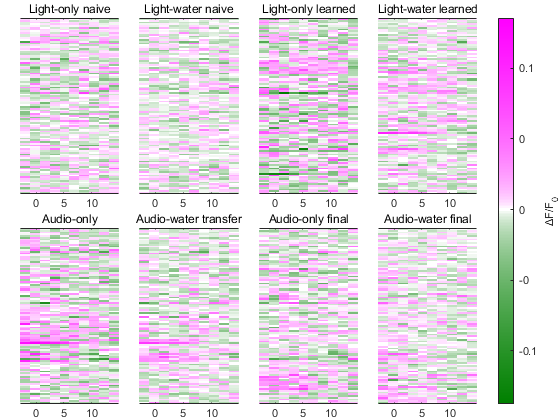

## 输入参数

NTATS(:,1)cell，作图数据，每个元胞对应一个泳道，元胞内是矩阵，第1维是不同的细胞，将作图为不同行；第2维是回合内的时间轴，将作图到同一行。通常应从HeatmapSort取得数据。

Flags1,Flags2,…(1,1)UniExp.Flags，指定功能旗帜，详见Flags枚举类的“LanearHeatmap旗帜”节

### 名称值参数

ImagescStyle(1,:)cell=cell(1,0)，本函数调用imagesc绘图，此处指定要传递给imagesc的其它参数。建议至少设置XData，保证XY坐标尺度正确。

LMHColor(3,3)double=[0,0.5,0;1,1,1;1,0,1]，指定最小、0、最大三个数值大小节点的颜色，其它数值将执行平方根插值，得到颜色映射表。

SubTitles(1,:)string，每个泳道的小标题。如不指定，将不显示小标题。

Layout(1,1)matlab.graphics.layout.TiledChartLayout=tiledlayout('flow',TileSpacing='tight',Padding='tight')，指定泳道布局对象，可用tiledlayout函数取得

## 返回值

Layout(1,1)matlab.graphics.layout.TiledChartLayout，泳道布局对象，可用于作图后期修饰

Axes(:,:)matlab.graphics.axis.Axes，每个泳道的坐标轴对象，可用于作图后期修饰。注意，第1维对应泳道布局水平排列，第2维对应泳道布局垂直分行。

**See also** [UniExp.HeatmapSort](matlab:doc UniExp.HeatmapSort) [UniExp.Flags](matlab:edit UniExp.Flags) [imagesc](matlab:doc imagesc) [tiledlayout](matlab:doc tiledlayout)

function [Layout,Axes]=LanearHeatmap(NTATS,Flags,options)
arguments
	NTATS
end
arguments(Repeating)
    Flags
end
arguments
	options.ImagescStyle=cell(1,0)
    options.LMHColor=[0,0.5,0;1,1,1;1,0,1];
	options.SubTitles
	options.Layout=tiledlayout('flow',TileSpacing='tight',Padding='tight')
end
HasFlags=num2cell(ismember([UniExp.Flags.HideXAxis,UniExp.Flags.HideYAxis],[Flags{:}]));
[HideXAxis,HideYAxis]=HasFlags{:};
HasSubTitles=isfield(options,'SubTitles');
NumLanes=numel(NTATS);
Sample=[NTATS{:}];
Min=min(Sample(:));
Max=max(Sample(:));
Limit=[Min,Max];
Steps=linspace(Min,Max,256);
LMHColor=options.LMHColor;
LowSteps=Steps(Steps<0)';
NumLowSteps=numel(LowSteps);
LowMap=MATLAB.ElMat.LinSpace(LMHColor(1,:),LMHColor(2,:),NumLowSteps,1);
LowMap=interp2(1:3,LowSteps,LowMap,1:3,rescale(-sqrt(-LowSteps),min(LowSteps),max(LowSteps)));
HighSteps=Steps(Steps>0)';
NumHighSteps=numel(HighSteps);
HighMap=MATLAB.ElMat.LinSpace(LMHColor(2,:),LMHColor(3,:),NumHighSteps,1);
HighMap=interp2(1:3,HighSteps,HighMap,1:3,rescale(sqrt(HighSteps),min(HighSteps),max(HighSteps)));
Colormap=[LowMap;HighMap];
RealAxes=gobjects(NumLanes,1);
Layout=options.Layout;
for a=1:NumLanes
	Ax=nexttile(Layout);
	imagesc(NTATS{a},options.ImagescStyle{:});
	clim(Limit);
	if HideXAxis
		Ax.XAxis.Visible="off";
	end
	if HideYAxis
		Ax.YAxis.Visible="off";
	end
	colormap(Colormap);
	if HasSubTitles
		title(options.SubTitles(a));
	end
	RealAxes(a)=Ax;
end
drawnow;
Axes=gobjects(Layout.GridSize)';
Axes(1:NumLanes)=RealAxes;
end